# ODE Equation

## **Second-order ODE:**

y'' + y = sin(x), y(0) = 0, y'(0) = 1

**Exact solution:**

y(x) = 1/2 (3 sin(x) - x cos(x))

% Define the ODE and its initial conditions
f = @(x, y) [y(2); sin(x) - y(1)];
y0 = [0; 1];

% Define the exact solution
y_exact = @(x) 1/2 * (3.*sin(x) - x.*cos(x));

% Define the time interval and step size
t_start = 0;
t_end = 10;
h = 0.1;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(length(y0), length(tspan));
y_forward(:,1) = y0;
for i = 2:length(tspan)
    y_forward(:,i) = y_forward(:,i-1) + h * f(tspan(i-1), y_forward(:,i-1));
end
time_forward = toc * 1000;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(length(y0), length(tspan));
y_backward(:,1) = y0;
for i = 2:length(tspan)
    y_backward(:,i) = (eye(length(y0)) - h * [0, 1; -1, 0]) \ y_backward(:,i-1) ...
        + h * [0; sin(tspan(i-1))];
     %y_backward(:,i) = y_backward(:,i-1) + h * f(tspan(i), y_backward(:,i));
end
time_backward = toc * 1000;

y_exact(tspan)

ans =          0    0.1000    0.2000    0.3000    0.3999    0.4997    0.5994    0.6986    0.7974    0.8953    0.9921    1.0873    1.1806    1.2715    1.3592    1.4432    1.5227    1.5970    1.6653    1.7266    1.7801    1.8249    1.8601    1.8848    1.8981    1.8991    1.8872    1.8616    1.8216    1.7668    1.6967    1.6110    1.5097    1.3927    1.2602    1.1126    0.9504    0.7742    0.5851    0.3839    0.1721   -0.0490   -0.2778   -0.5125   -0.7513   -0.9920   -1.2326   -1.4708   -1.7042   -1.9306


y_forward

y_forward =          0    0.1000    0.2000    0.3000    0.4000    0.4999    0.5998    0.6994    0.7987    0.8974    0.9953    1.0921    1.1873    1.2805    1.3712    1.4587    1.5424    1.6214    1.6950    1.7623    1.8224    1.8743    1.9171    1.9498    1.9715    1.9810    1.9776    1.9604    1.9286    1.8814    1.8183    1.7388    1.6425    1.5292    1.3989    1.2518    1.0881    0.9083    0.7133    0.5039    0.2813    0.0467   -0.1983   -0.4519   -0.7122   -0.9772   -1.2446   -1.5120   -1.7768   -2.0366
    1.0000    1.0000    1.0000    0.9999    0.9994    0.9983    0.9963    0.9928    0.9873    0.9791    0.9677    0.9523    0.9323    0.9067    0.8750    0.8365    0.7903    0.7361    0.6731    0.6010    0.5194    0.4281    0.3269    0.2161    0.0957   -0.0339   -0.1722   -0.3184   -0.4717   -0.6311   -0.7953   -0.9630   -1.1327   -1.3028   -1.4715   -1.6369   -1.7972   -1.9502   -2.0941   -2.2266   -2.3458   -2.4496   -2.5361   -2.6034   -2.6498   -2.6738   -2.6738   -2.6487   -2.5

y_backward

y_backward =          0    0.0990    0.1961    0.2912    0.3845    0.4759    0.5657    0.6536    0.7398    0.8243    0.9068    0.9873    1.0655    1.1412    1.2142    1.2839    1.3500    1.4119    1.4691    1.5211    1.5671    1.6065    1.6386    1.6627    1.6781    1.6842    1.6801    1.6655    1.6395    1.6019    1.5520    1.4897    1.4146    1.3267    1.2259    1.1125    0.9866    0.8487    0.6994    0.5394    0.3696    0.1910    0.0047   -0.1878   -0.3852   -0.5859   -0.7882   -0.9904   -1.1906   -1.3869
    1.0000    0.9901    0.9805    0.9712    0.9623    0.9537    0.9451    0.9362    0.9266    0.9159    0.9036    0.8890    0.8715    0.8506    0.8256    0.7957    0.7605    0.7192    0.6715    0.6168    0.5547    0.4850    0.4074    0.3220    0.2288    0.1279    0.0197   -0.0953   -0.2165   -0.3432   -0.4744   -0.6093   -0.7466   -0.8851   -1.0235   -1.1603   -1.2940   -1.4231   -1.5461   -1.6612   -1.7669   -1.8617   -1.9440   -2.0124   -2.0655   -2.1020   -2.1210   -2.1213   -2.


% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward(1,:))

error_forward =          0    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0008    0.0013    0.0021    0.0033    0.0047    0.0067    0.0091    0.0120    0.0155    0.0196    0.0244    0.0297    0.0357    0.0423    0.0494    0.0571    0.0651    0.0734    0.0819    0.0904    0.0988    0.1070    0.1146    0.1216    0.1277    0.1328    0.1365    0.1387    0.1391    0.1377    0.1341    0.1283    0.1200    0.1092    0.0957    0.0795    0.0607    0.0391    0.0148    0.0120    0.0412    0.0726    0.1059


error_backward = abs(y_exact(tspan) - y_backward(1,:))

error_backward =          0    0.0010    0.0039    0.0088    0.0154    0.0238    0.0337    0.0450    0.0575    0.0710    0.0853    0.1001    0.1151    0.1302    0.1450    0.1593    0.1728    0.1851    0.1961    0.2055    0.2130    0.2184    0.2215    0.2221    0.2199    0.2150    0.2071    0.1961    0.1820    0.1649    0.1446    0.1213    0.0951    0.0660    0.0343    0.0002    0.0362    0.0744    0.1143    0.1555    0.1975    0.2400    0.2826    0.3248    0.3661    0.4062    0.4444    0.4804    0.5137    0.5437



% Error per
per_error_arr_fe = abs(error_forward ./ y_exact(tspan) * 100)

per_error_arr_fe =        NaN    0.0001    0.0013    0.0062    0.0170    0.0362    0.0659    0.1082    0.1649    0.2376    0.3277    0.4365    0.5650    0.7139    0.8840    1.0759    1.2900    1.5267    1.7864    2.0697    2.3770    2.7092    3.0672    3.4523    3.8662    4.3114    4.7910    5.3094    5.8724    6.4882    7.1681    7.9284    8.7931    9.7985   11.0030   12.5053   14.4871   17.3227   21.9250   31.2563   63.4435  195.2222   28.6320   11.8341    5.1986    1.4927    0.9725    2.7998    4.2585    5.4871


per_error_arr_be = abs(error_backward ./ y_exact(tspan) * 100)

per_error_arr_be =        NaN    0.9900    1.9691    2.9285    3.8615    4.7618    5.6236    6.4420    7.2124    7.9313    8.5956    9.2031    9.7520   10.2412   10.6701   11.0382   11.3455   11.5920   11.7779   11.9030   11.9671   11.9694   11.9086   11.7824   11.5878   11.3197   10.9716   10.5340    9.9937    9.3324    8.5239    7.5309    6.2980    4.7404    2.7228    0.0148    3.8070    9.6156   19.5400   40.4911  114.7553  489.4988  101.7069   63.3624   48.7317   40.9426   36.0552   32.6633   30.1395   28.1610



% Mean Error Per
mean_error_fe = mean(per_error_arr_fe(2:end))

mean_error_fe = 18.2120

mean_error_be = mean(per_error_arr_be(2:end))

mean_error_be = 31.5799

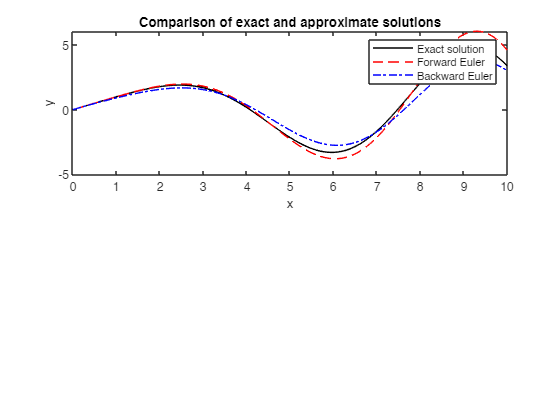



% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward(1,:), 'r--', tspan, y_backward(1,:), 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 10.447000 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 7.269200 seconds


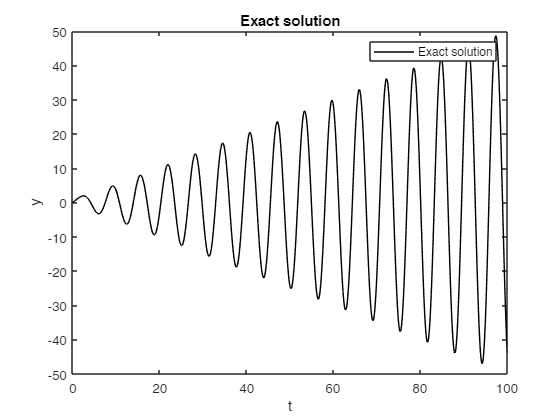

figure;
plot(tspan, y_exact(tspan), 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');